T_set = 25;     % °C
H_set = 85;     % %
T_measured = 26;
H_measured = 86;

eT = T_measured - T_set;
eH = H_set - H_measured;



fis = mamfis('Name','HumidifierController');


%Adding Inputs
fis = addInput(fis,[-30 30],'Name','HumidityError');
fis = addInput(fis,[-5 5],'Name','TemperatureError');

%Adding  Input Membership Functions
fis = addMF(fis,'TemperatureError','trimf',[-5 -5 0],'Name','Cold');
fis = addMF(fis,'TemperatureError','trimf',[-2 0 2],'Name','Normal');
fis = addMF(fis,'TemperatureError','trimf',[0 5 5],'Name','Hot');

fis = addMF(fis,'HumidityError','trimf',[-30 -30 0],'Name','Wet');
fis = addMF(fis,'HumidityError','trimf',[-10 0 10],'Name','OK');
fis = addMF(fis,'HumidityError','trimf',[0 30 30],'Name','Dry');


%Adding Output
fis = addOutput(fis,[0 100],'Name','HumidifierLevel');

%Adding  Output Membership Functions
fis = addMF(fis,'HumidifierLevel','trimf',[0 0 25],'Name','OFF');
fis = addMF(fis,'HumidifierLevel','trimf',[20 40 60],'Name','LOW');
fis = addMF(fis,'HumidifierLevel','trimf',[50 70 90],'Name','MEDIUM');
fis = addMF(fis,'HumidifierLevel','trimf',[80 100 100],'Name','HIGH');

rules = [
    "IF HumidityError IS Dry THEN HumidifierLevel IS HIGH"
    "IF HumidityError IS OK THEN HumidifierLevel IS LOW"
    "IF HumidityError IS Wet THEN HumidifierLevel IS OFF"

    "IF TemperatureError IS Hot AND HumidityError IS Dry THEN HumidifierLevel IS HIGH"
    "IF TemperatureError IS Cold AND HumidityError IS Wet THEN HumidifierLevel IS OFF"
    "IF TemperatureError IS Normal AND HumidityError IS Dry THEN HumidifierLevel IS MEDIUM"
];

fis = addRule(fis, rules);


output = evalfis(fis,[eH eT])

output = 38.9756

pwm = round((output/100)*255)

pwm = 99

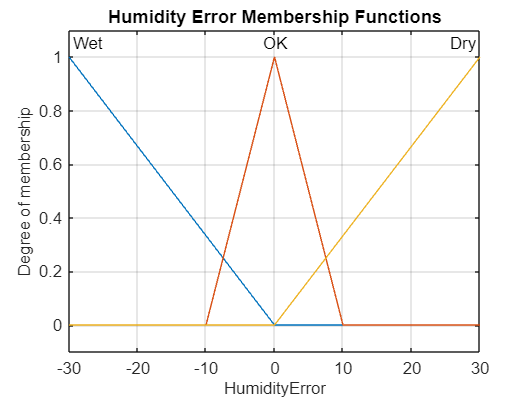

figure
plotmf(fis,'input',1)   % HumidityError is input #1
title('Humidity Error Membership Functions')
grid on

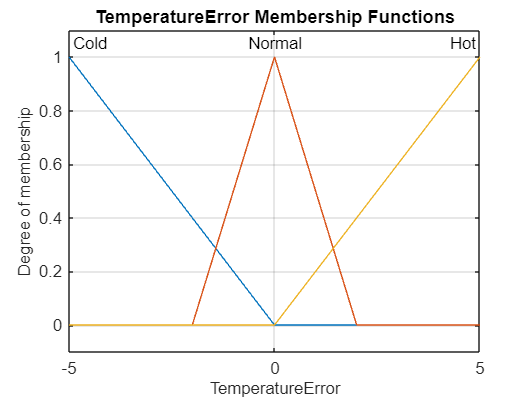

figure
plotmf(fis,'input',2)   % TemperatureError is input #2
title('TemperatureError Membership Functions')
grid on

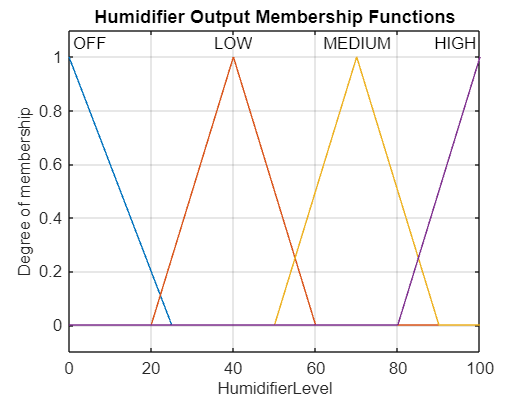

figure
plotmf(fis,'output',1)
title('Humidifier Output Membership Functions')
grid on

testCases = [
    25  85 ;   % Ideal
    26  70 ;   % Slightly hot, dry
    24  90 ;   % Cool and wet
    28  60 ;   % Hot and very dry
    22  95 ;   % Cold and very wet
];

disp('T  H  Humidifier%  PWM')

T  H  Humidifier%  PWM



for i = 1:size(testCases,1)

    T_measured = testCases(i,1);
    H_measured = testCases(i,2);

    eT = T_measured - T_set;
    eH = H_set - H_measured;

    output = evalfis(fis,[eH eT]);
    pwm = round((output/100)*255);

    fprintf('%2.0f %2.0f   %6.2f     %3d\n', ...
        T_measured, H_measured, output, pwm);

end

25 85    40.00     102
26 70    77.23     197
24 90    34.23      87
28 60    93.47     238
22 95    10.30      26


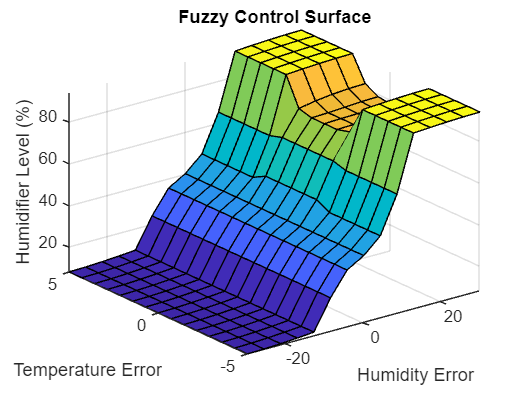

figure
gensurf(fis)
xlabel('Humidity Error')
ylabel('Temperature Error')
zlabel('Humidifier Level (%)')
title('Fuzzy Control Surface')